# F1 Power Unit: Fuel Energy, Thermal Efficiency and Power Output

The objective is to investigate how fuel-energy-flow restriction and brake thermal efficiency influence the theoretical power available from an F1 internal combustion engine. 

The best place to start would be fundamental thermodynamics, and then extend the capabilities of the model to consider engine speed, torque, and hybrid deployment. 

## Step 1: Fuel Energy & Engine Brake Power

Starting with the equation for brake power $P_b$:


$$P_b =\eta {\;}_b \dot{E_f }$$


Where $\eta {\;}_b$ is the brake thermal efficiency and $\dot{E_f }$ is the fuel-energy-flow rate. 

In 2026, with the new F1 regulations, we can initially use maximum fuel-energy-flow ceiling of 3000 MJ/h, which corresponds to 833.33 kW. 

The expected results:

clear; clc; close all;

% Figure Export Settings

% Create a folder for exported figures
figureFolder = 'figures';

if ~exist(figureFolder, 'dir')
    mkdir(figureFolder);
end

% Export resolution
exportDPI = 300;

% Fuel energy input
fuelEnergyFlow_MJh = 3000;  % MJ/h, 2026 maximum
fuelPower_kW = fuelEnergyFlow_MJh * 1000 / 3600; % Convert MJ/h to kW

% Brake thermal efficiency
estimated_te = linspace(0.35, 0.55, 101);
brake_power_kW = estimated_te .* fuelPower_kW;

% Compare efficiency
estimated_te1 = 0.45;
estimated_te2 = 0.50;

P1 = estimated_te1 * fuelPower_kW; 
P2 = estimated_te2 * fuelPower_kW;

P_delta = P2 - P1;

fprintf('Fuel power: %.1f kW\n', fuelPower_kW);

Fuel power: 833.3 kW


fprintf('Brake power at 45%%: %.2f kW\n', P1);

Brake power at 45%: 375.00 kW


fprintf('Brake power at 50%%: %.2f kW\n', P2);

Brake power at 50%: 416.67 kW


fprintf('Additional power: %.2f kW\n', P_delta);

Additional power: 41.67 kW


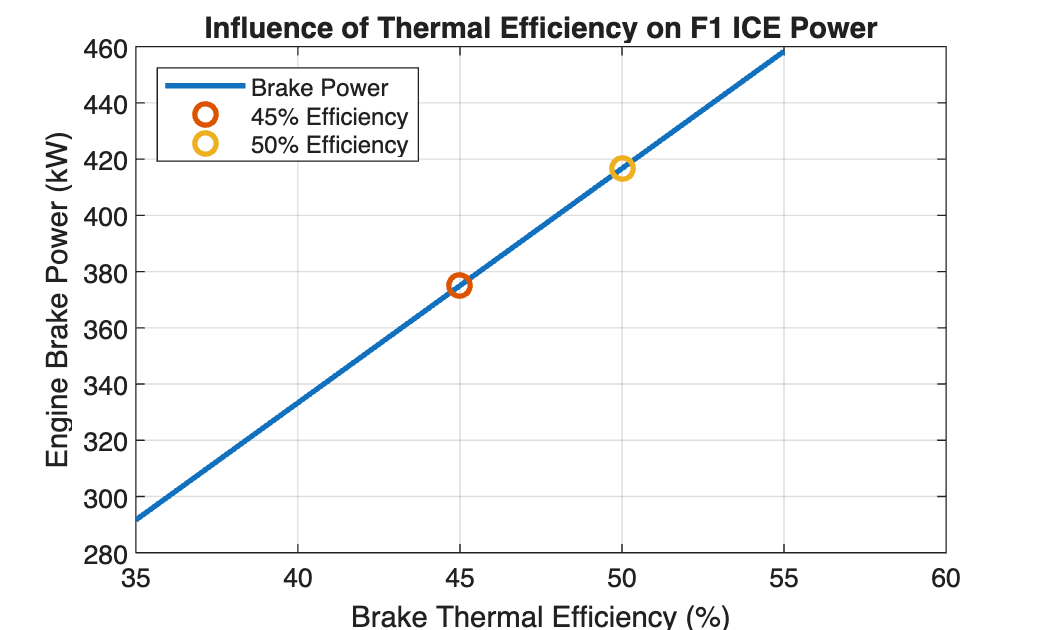


% Plot efficiency against brake power
figure('Color', 'w');
plot(estimated_te * 100, brake_power_kW, 'LineWidth', 2);
hold on;
plot(estimated_te1 * 100, P1, 'o', 'MarkerSize', 8, 'LineWidth', 2);
plot(estimated_te2 * 100, P2, 'o', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('Brake Thermal Efficiency (%)');
ylabel('Engine Brake Power (kW)');
title('Influence of Thermal Efficiency on F1 ICE Power');
legend('Brake Power', '45% Efficiency', '50% Efficiency', 'Location', 'northwest');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step1_Efficiency_vs_brake_power.png'), 'Resolution', exportDPI);

This graph shows how engine brake power increases with thermal efficiency under fixed fuel-energy-flow ceiling. 

## Step 2: Engine Speed, Torque, and Regulatory Limit

We will now build on this model to investigate the following relationship:


$$P_b =T\omega =\frac{2\pi \textrm{NT}\;}{60}$$


Therefore, 


$$T=\frac{60P_b }{2\pi N}$$


Where $N$ is the engine speed in RPM and $P_b$ is expressed in watts. 

This gives us the ability to generate theoretical torque and power curves against engine speed. 

We still need to include the actual FIA fuel-energy-flow restrictions, rather than assuming that the full 3000 MJ/h is available for the entire engine-speed range. In Article C, the maximum permitted fuel energy flow is:


$$\dot{E_f } \left(N\right)=\left\lbrace \begin{array}{ll}
0\ldotp 27N+165, & N<10500\;\textrm{rpm}\\
3000, & N\ge 10500\;\textrm{rpm}
\end{array}\right.$$


There are additional restrictions relating to partial-load operation. However, here we are investigating the full-load, speed-dependent fuel-energy ceiling. 

We should distinguish the regulatory fuel-energy ceiling from a realistic engine performance curve since the real brake thermal efficiency changes with speed and load. 

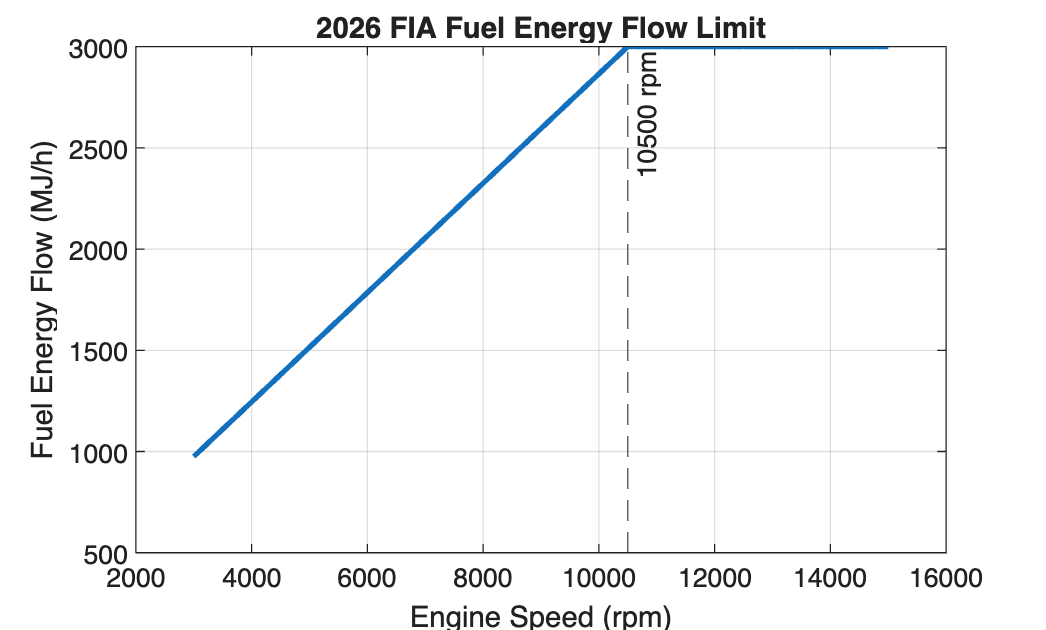

clear; clc; close all;

% Figure Export Settings

% Create a folder for exported figures
figureFolder = 'figures';

if ~exist(figureFolder, 'dir')
    mkdir(figureFolder);
end

% Export resolution
exportDPI = 300;

% Engine speed range
rpm = 3000:100:15000;

% Brake thermal efficiencies
estimated_te1 = 0.45;
estimated_te2 = 0.50;

% 2026 FIA fuel energy flow restrictions
fuelEnergyFlow = zeros(size(rpm));

for i = 1:length(rpm)
    if rpm(i) < 10500
        fuelEnergyFlow(i) = 0.27 * rpm(i) + 165;
    else
        fuelEnergyFlow(i) = 3000;
    end
end

fuelPower = fuelEnergyFlow * 1000 / 3600; % Convert MJ/h to kW

% Calculate engine brake power
P_45 = estimated_te1 .* fuelPower;
P_50 = estimated_te2 .* fuelPower;

% Calculate engine torque
torque_45_Nm = P_45 * 1000 ./ (2 * pi * rpm / 60);
torque_50_Nm = P_50 * 1000 ./ (2 * pi * rpm / 60);

% Plot fuel energy flow against engine speed
figure('Color','w');
plot(rpm, fuelEnergyFlow, 'LineWidth', 2);
xlabel('Engine Speed (rpm)');
ylabel('Fuel Energy Flow (MJ/h)');
title('2026 FIA Fuel Energy Flow Limit');
xline(10500, '--', '10500 rpm');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step2_fuel_energy_flow_vs_engine_speed.png'), 'Resolution', exportDPI);

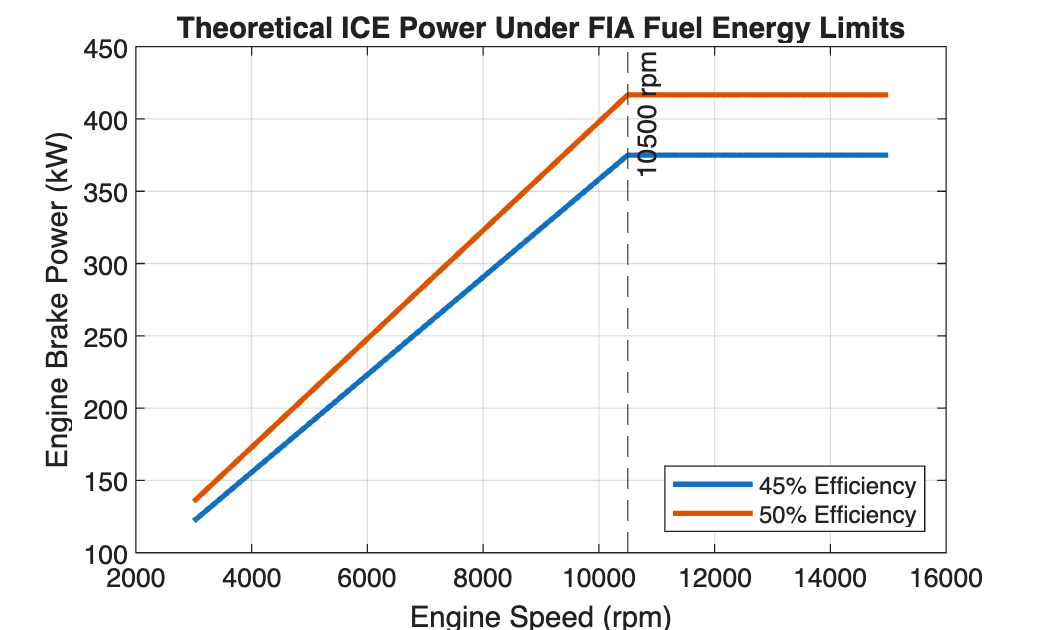


% Plot engine brake power against engine speed
figure('Color','w');
plot(rpm, P_45, 'LineWidth', 2);
hold on;
plot(rpm, P_50, 'LineWidth', 2);
xline(10500, '--', '10500 rpm');
xlabel('Engine Speed (rpm)');
ylabel('Engine Brake Power (kW)');
title('Theoretical ICE Power Under FIA Fuel Energy Limits');
legend('45% Efficiency', '50% Efficiency', 'Location', 'southeast');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step2_engine_brake_power_vs_engine_speed.png'), 'Resolution', exportDPI);

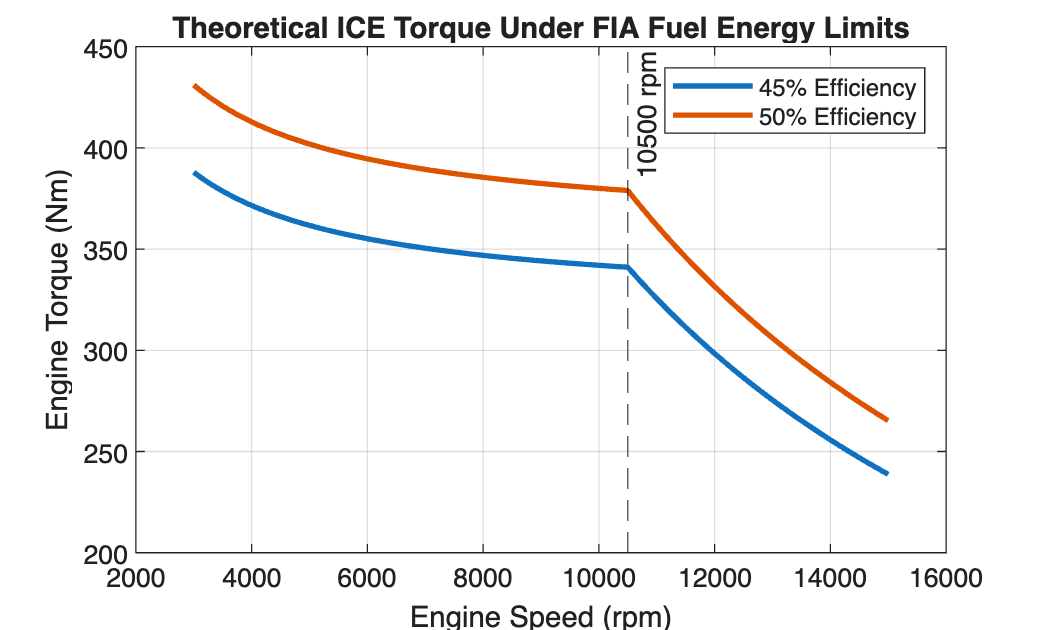


% Plot engine torque against engine speed
figure('Color','w');
plot(rpm, torque_45_Nm, 'LineWidth', 2);
hold on;
plot(rpm, torque_50_Nm, 'LineWidth', 2);
xline(10500, '--', '10500 rpm');
xlabel('Engine Speed (rpm)');
ylabel('Engine Torque (Nm)');
title('Theoretical ICE Torque Under FIA Fuel Energy Limits');
legend('45% Efficiency', '50% Efficiency', 'Location', 'northeast');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step2_engine_torque_vs_engine_speed.png'), 'Resolution', exportDPI);


% Results at 10500 rpm
idx = find(rpm == 10500);
fprintf('Engine speed: %.0f rpm\n', rpm(idx));

Engine speed: 10500 rpm


## Step 3: Hybrid Powertrain Extension

Now that the combustion-engine model is working, the electric part of the power unit can now be introduced. 

This includes investigating how the electrical power deployment, energy storage, and operating constraints influence the total powertrain performance. 

It is quite difficult to try and simply add a constant electrical power contribution. It would be better to create an entirely separate model. 

This model will simulate the reaction between ICE brake power, MGU-K electrical deployment, MGU-K energy harvesting, and energy storage. 

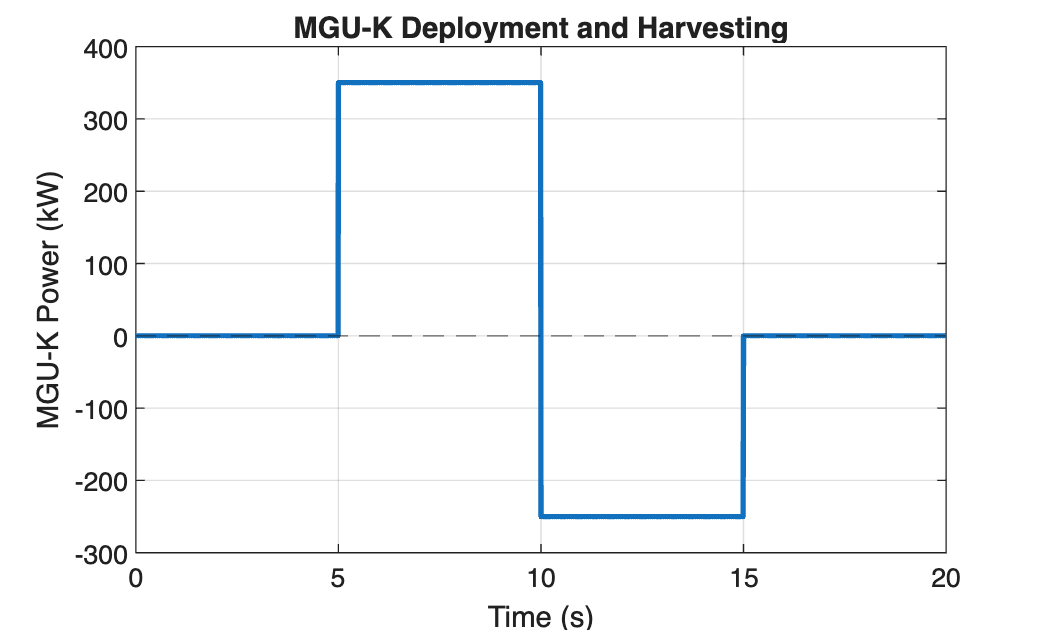

clear; clc; close all;

% Figure Export Settings

% Create a folder for exported figures
figureFolder = 'figures';

if ~exist(figureFolder, 'dir')
    mkdir(figureFolder);
end

% Export resolution
exportDPI = 300;

% Model parameters
ICE_efficiency = 0.50;
% Fuel energy input
fuelEnergyFlow_MJh = 3000;  % MJ/h, 2026 maximum
fuelPower_kW = fuelEnergyFlow_MJh * 1000 / 3600; % Convert MJ/h to kW
% Maximum ICE brake power
P_ICE = ICE_efficiency * fuelPower_kW;
% MGU-K operating powers (kW)
P_deployment = 350;
P_harvesting = -250;
% Initial usable stored energy (MJ)
E_initial = 4;
% Simulation parameters
dt = 0.01;
time = 0:dt:20;
% Energy storage
E_store = zeros(size(time));
E_store(1) = E_initial;
% MGU-K power
P_MGUK = zeros(size(time));
% Total power
P_total = zeros(size(time));

% Define operating strategy
for i = 1:length(time)
    if time(i) < 5
        % ICE only
        P_MGUK(i) = 0;
    elseif time(i) < 10
        % Electrical deployment
        P_MGUK(i) = P_deployment;
    elseif time(i) < 15
        % Energy harvesting
        P_MGUK(i) = P_harvesting;
    else
        % ICE only
        P_MGUK(i) = 0;
    end
end

% Calculate energy storage and total power
for i = 1:length(time)-1
    % Prevent deployment when energy is depleted
    if E_store(i) <= 0 && P_MGUK(i) > 0
        P_MGUK(i) = 0;
    end
    % Update stored energy
    E_store(i+1) = E_store(i) - P_MGUK(i) * dt / 1000;
    % Total mechanical power
    P_total(i) = P_ICE + P_MGUK(i);
end
P_total(end) = P_ICE + P_MGUK(end);

% Plot MGU-K power
figure('Color','w');
plot(time, P_MGUK, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('MGU-K Power (kW)');
title('MGU-K Deployment and Harvesting');
yline(0, '--');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step3_MGU-K_Power.png'), 'Resolution', exportDPI);

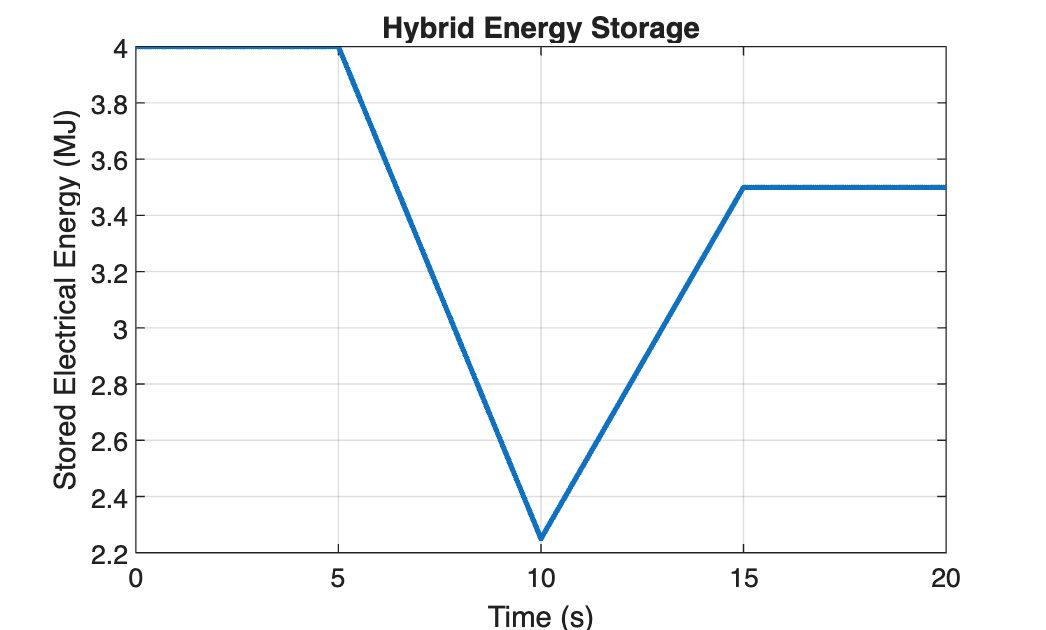


% Plot stored energy
figure('Color','w');
plot(time, E_store, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Stored Electrical Energy (MJ)');
title('Hybrid Energy Storage');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step3_stored_energy.png'), 'Resolution', exportDPI);

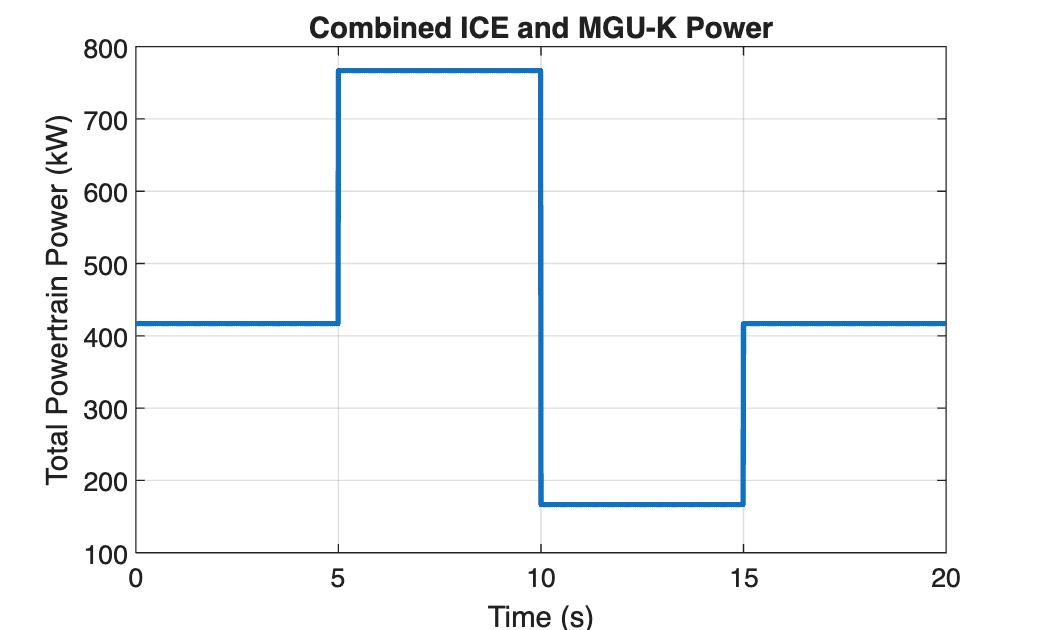


% Plot total power
figure('Color','w');
plot(time, P_total, 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Total Powertrain Power (kW)');
title('Combined ICE and MGU-K Power');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step3_total_power.png'), 'Resolution', exportDPI);

## Step 4: Comparing the 2026 and 2027 Regulations

The FIA has made a change to the regulations for the 2027 season to give a 5% increase in permitted fuel-energy flow for 2027, alongside changes to the balance between combustion engine and electrical power. This gives rise to an important engineering question:

How much additional ICE power can the 2027 regulations provide, and how does this compare with improving engine thermal efficiency?

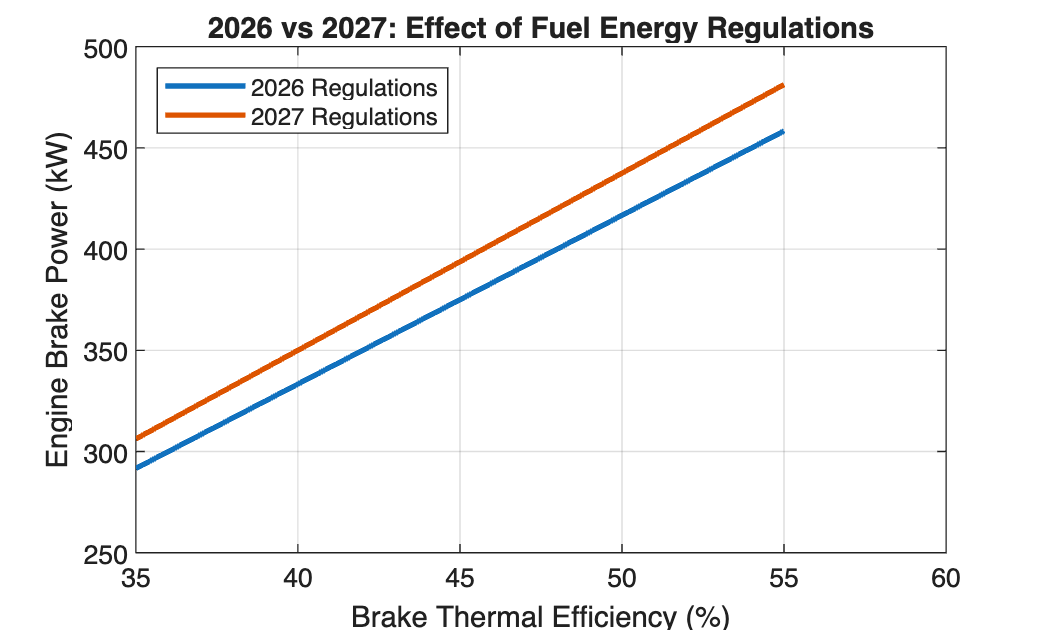

clear; clc; close all;

% Figure Export Settings

% Create a folder for exported figures
figureFolder = 'figures';

if ~exist(figureFolder, 'dir')
    mkdir(figureFolder);
end

% Export resolution
exportDPI = 300;

% Maximum fuel energy flow (MJ/h)
fuelFlow_2026 = 3000;
fuelFlow_2027 = 3150;
% Convert to kW
fuelPower_2026 = fuelFlow_2026 * 1000 / 3600;
fuelPower_2027 = fuelFlow_2027 * 1000 / 3600;
% Brake thermal efficiency range
eta = linspace(0.35, 0.55, 101);
% Theoretical brake power
P_2026 = eta .* fuelPower_2026;
P_2027 = eta .* fuelPower_2027;

% Plot comparison
figure('Color','w');
plot(eta*100, P_2026, 'LineWidth', 2);
hold on;
plot(eta*100, P_2027, 'LineWidth', 2);
xlabel('Brake Thermal Efficiency (%)');
ylabel('Engine Brake Power (kW)');
title('2026 vs 2027: Effect of Fuel Energy Regulations');
legend('2026 Regulations', '2027 Regulations', 'Location', 'northwest');
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step4_2026_vs_2027_Fuel_Energy_Comparison.png'), 'Resolution', exportDPI);


% Compare results at 50% efficiency
eta_ref = 0.50;
P26 = eta_ref * fuelPower_2026;
P27 = eta_ref * fuelPower_2027;
fprintf('\n===== 2026 vs 2027 COMPARISON =====\n');


===== 2026 vs 2027 COMPARISON =====


fprintf('2026 ICE Power: %.2f kW\n', P26);

2026 ICE Power: 416.67 kW


fprintf('2027 ICE Power: %.2f kW\n', P27);

2027 ICE Power: 437.50 kW


fprintf('Additional ICE Power: %.2f kW\n', P27-P26);

Additional ICE Power: 20.83 kW


## Step 5: Thermal Efficiency vs Regulatory Fuel-Energy Increase

The objective is to investigate which scenario produces a greater increase in theoretical ICE brake power:

- Scenario A: Improving brake thermal efficiency from 45% to 50% while retaining the 2026 fuel-energy-flow limit.

- Scenario B: Increasing the permitted fuel-energy input by 5% for 2027 while maintaining 45% brake thermal efficiency.

- Scenario C: Combining the 2027 fuel-energy increase with 50% brake thermal efficiency.

We use the maximum fuel-energy-flow values from the previous step, so this comparison represents operation at the regulatory ceiling rather than the complete engine-speed range. 

clear; clc; close all;

% Figure Export Settings

% Create a folder for exported figures
figureFolder = 'figures';

if ~exist(figureFolder, 'dir')
    mkdir(figureFolder);
end

% Export resolution
exportDPI = 300;

% Maximum fuel energy flow (MJ/h)
fuelFlow_2026 = 3000;
fuelFlow_2027 = 3150;
eta_baseline = 0.45;
eta_improved = 0.50;
% Convert to kW
fuelPower_2026 = fuelFlow_2026 * 1000 / 3600;
fuelPower_2027 = fuelFlow_2027 * 1000 / 3600;

% Calculate power for each scenario

% Baseline: 2026 regulations, 45% efficiency
P_baseline = eta_baseline * fuelPower_2026;
% Scenario A: Improved thermal efficiency
P_efficiency = eta_improved * fuelPower_2026;
% Scenario B: Increased fuel-energy allowance
P_regulation = eta_baseline * fuelPower_2027;
% Scenario C: Both improvements
P_combined = eta_improved * fuelPower_2027;

% Calculate improvements relative to baseline
delta_efficiency = P_efficiency - P_baseline;
delta_regulation = P_regulation - P_baseline;
delta_combined = P_combined - P_baseline;
improvement_ratio = delta_efficiency / delta_regulation;

% Display numerical results
fprintf('\n===== STEP 5: ENGINE POWER COMPARISON =====\n');


===== STEP 5: ENGINE POWER COMPARISON =====


fprintf('Baseline power: %.2f kW\n', P_baseline);

Baseline power: 375.00 kW


fprintf('Efficiency improvement: +%.2f kW\n', delta_efficiency);

Efficiency improvement: +41.67 kW


fprintf('Regulatory fuel-energy increase: +%.2f kW\n', delta_regulation);

Regulatory fuel-energy increase: +18.75 kW


fprintf('Combined improvement: +%.2f kW\n', delta_combined);

Combined improvement: +62.50 kW


fprintf('Efficiency / Regulation improvement ratio: %.2f\n', improvement_ratio);

Efficiency / Regulation improvement ratio: 2.22


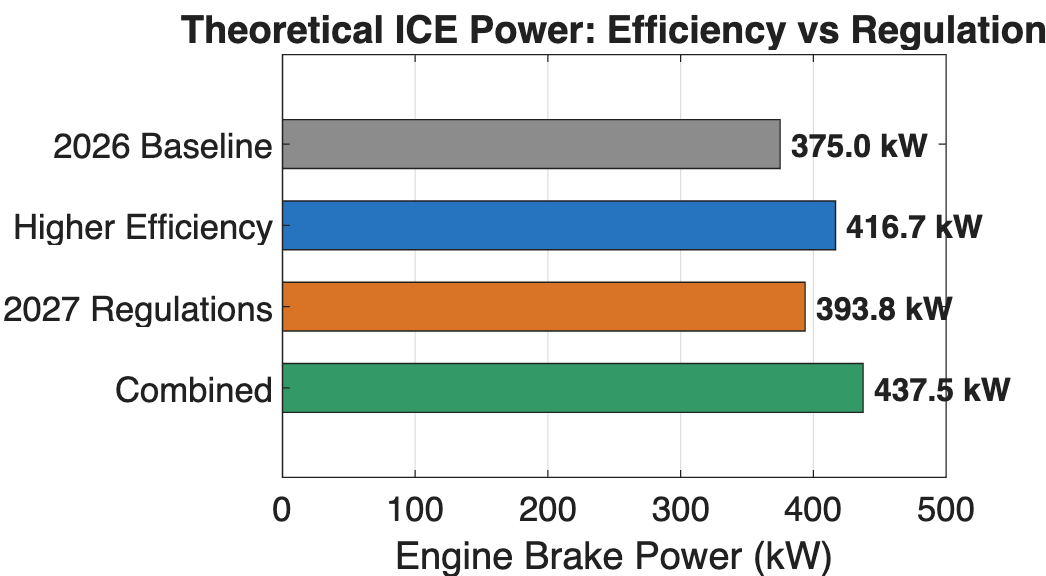


% Plot comparison of theoretical engine power
scenario_names = {'2026 Baseline', 'Higher Efficiency', '2027 Regulations', 'Combined'};
scenario_power = [P_baseline, P_efficiency, P_regulation, P_combined];
figure('Color', 'w', 'Position', [100 100 1000 550]);
% Horizontal bar chart
b = barh(scenario_power, 0.6);
b.FaceColor = 'flat';
b.CData = [0.55 0.55 0.55;0.15 0.45 0.75;0.85 0.45 0.15;0.20 0.60 0.40];
% Category labels
yticks(1:4);
yticklabels(scenario_names);
% Display baseline at the top
set(gca, 'YDir', 'reverse');
xlabel('Engine Brake Power (kW)');
title('Theoretical ICE Power: Efficiency vs Regulation');
xlim([0 500]);
grid on;
ax = gca;
ax.XGrid = 'on';
ax.YGrid = 'off';
ax.FontSize = 13;
% Add numerical values at the end of each bar
for i = 1:length(scenario_power)
    text(scenario_power(i) + 8, i, sprintf('%.1f kW', scenario_power(i)), 'VerticalAlignment', 'middle', 'FontWeight', 'bold', 'FontSize', 12);
end
% Export figure
exportgraphics(gcf, fullfile(figureFolder, 'Step5_Total_Power.png'), 'Resolution', 300);

% Add power labels above bars
for i = 1:length(scenario_power)
    text(i, scenario_power(i) + 8, sprintf('%.1f kW', scenario_power(i)), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end

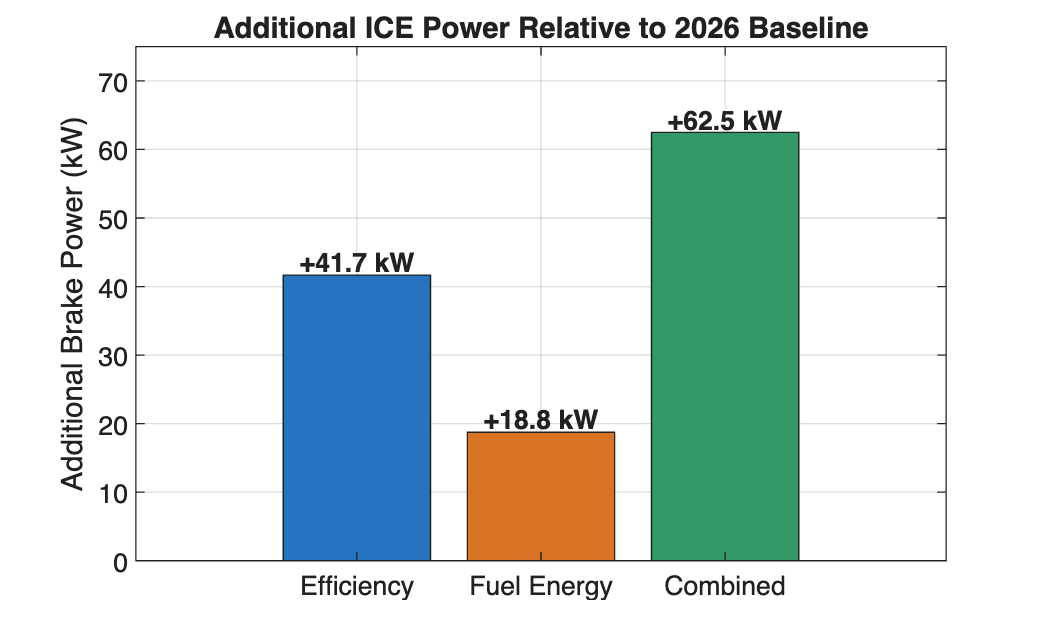


% Plot additional power relative to baseline
scenario_improvements = [delta_efficiency, delta_regulation, delta_combined];
figure('Color', 'w');
b2 = bar(scenario_improvements);
b2.FaceColor = 'flat';
b2.CData = [0.15 0.45 0.75; 0.85 0.45 0.15; 0.20 0.60 0.40];
xticks(1:3);
xticklabels({'Efficiency', 'Fuel Energy', 'Combined'});
xtickangle(0);
ylabel('Additional Brake Power (kW)');
title('Additional ICE Power Relative to 2026 Baseline');
ylim([0 75]);
grid on;
exportgraphics(gcf, fullfile(figureFolder, 'Step5_Additional_ICE_Power_Rel_Baseline.png'), 'Resolution', exportDPI);

for i = 1:length(scenario_improvements)
    text(i, scenario_improvements(i) + 2, sprintf('+%.1f kW', scenario_improvements(i)), 'HorizontalAlignment', 'center', 'FontWeight', 'bold');
end